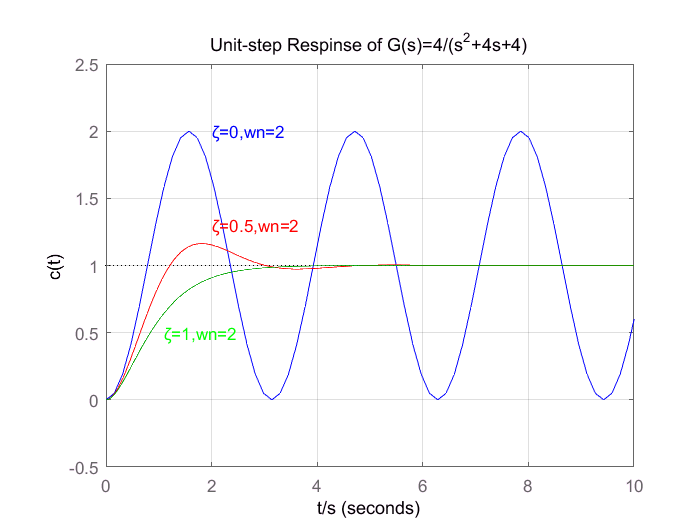

%实验1.1
% wn=2，阻尼比为0——震荡
x=0;
num=[4]; %定义分子多项式
den=[1 4*x 4]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys,'b') %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
text(2,2,'ζ=0,wn=2','Color','blue')
title('Unit-step Respinse of G(s)=4/(s^2+4)') ; %给图形加上标题名
hold on;

% wn=2，阻尼比为0.5——欠阻尼，有超调
x=0.5;
num=[4]; %定义分子多项式
den=[1 4*x 4]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys,'r') %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
text(2,1.3,'ζ=0.5,wn=2','Color','red')
title('Unit-step Respinse of G(s)=4/(s^2+2s+4)') ; %给图形加上标题名
hold on;

% wn=2，阻尼比为1.0——临界阻尼
x=1;
num=[4]; %定义分子多项式
den=[1 4*x 4]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys,'g') %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
text(1.1,0.5,'ζ=1,wn=2','Color','green')
title('Unit-step Respinse of G(s)=4/(s^2+4s+4)') ; %给图形加上标题名

hold off;

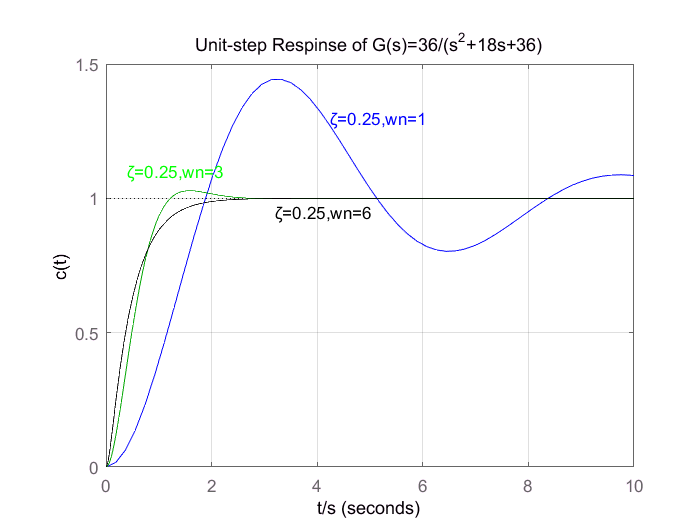

% 1.1.2 阻尼比为0.25，wn=1
num=[0 0 1]; %定义分子多项式
den=[1 0.5 1]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys,'b') %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 30]);
text(4.25,1.3,'ζ=0.25,wn=1','Color','b')
title('Unit-step Respinse of G(s)=1/(s^2+0.5s+1),') ; %给图形加上标题名
hold on;

% 阻尼比为0.25，wn=3
num=[0 0 9]; %定义分子多项式
den=[1 4.5 9]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys,'g') %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
text(0.4,1.1,'ζ=0.25,wn=3','Color','green')
title('Unit-step Respinse of G(s)=9/(s^2+4.5s+9),') ; %给图形加上标题名
hold on;

% 阻尼比为0.25，wn=6
num=[0 0 36]; %定义分子多项式
den=[1 18 36]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys,'black') %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
text(3.2,0.95,'ζ=0.25,wn=6');
title('Unit-step Respinse of G(s)=36/(s^2+18s+36)') ; %给图形加上标题名
hold off;


%1.2  直接求根判稳——不稳定（有两个根不在左半平面）
roots([2,1,3,5,10])

ans =    0.7555 + 1.4444i
   0.7555 - 1.4444i
  -1.0055 + 0.9331i
  -1.0055 - 0.9331i



% 劳斯判据——不稳定（符号变换了两次）
syms EPS %定义符号
den=[2,1,3,5,10];
ra=routh(den,EPS)

$$ra = \left(\begin{array}{ccc} 2 & 3 & 10\\ 1 & 5 & 0\\ -7 & 10 & 0\\ \frac{45}{7} & 0 & 0\\ 10 & 0 & 0 \end{array}\right)$$

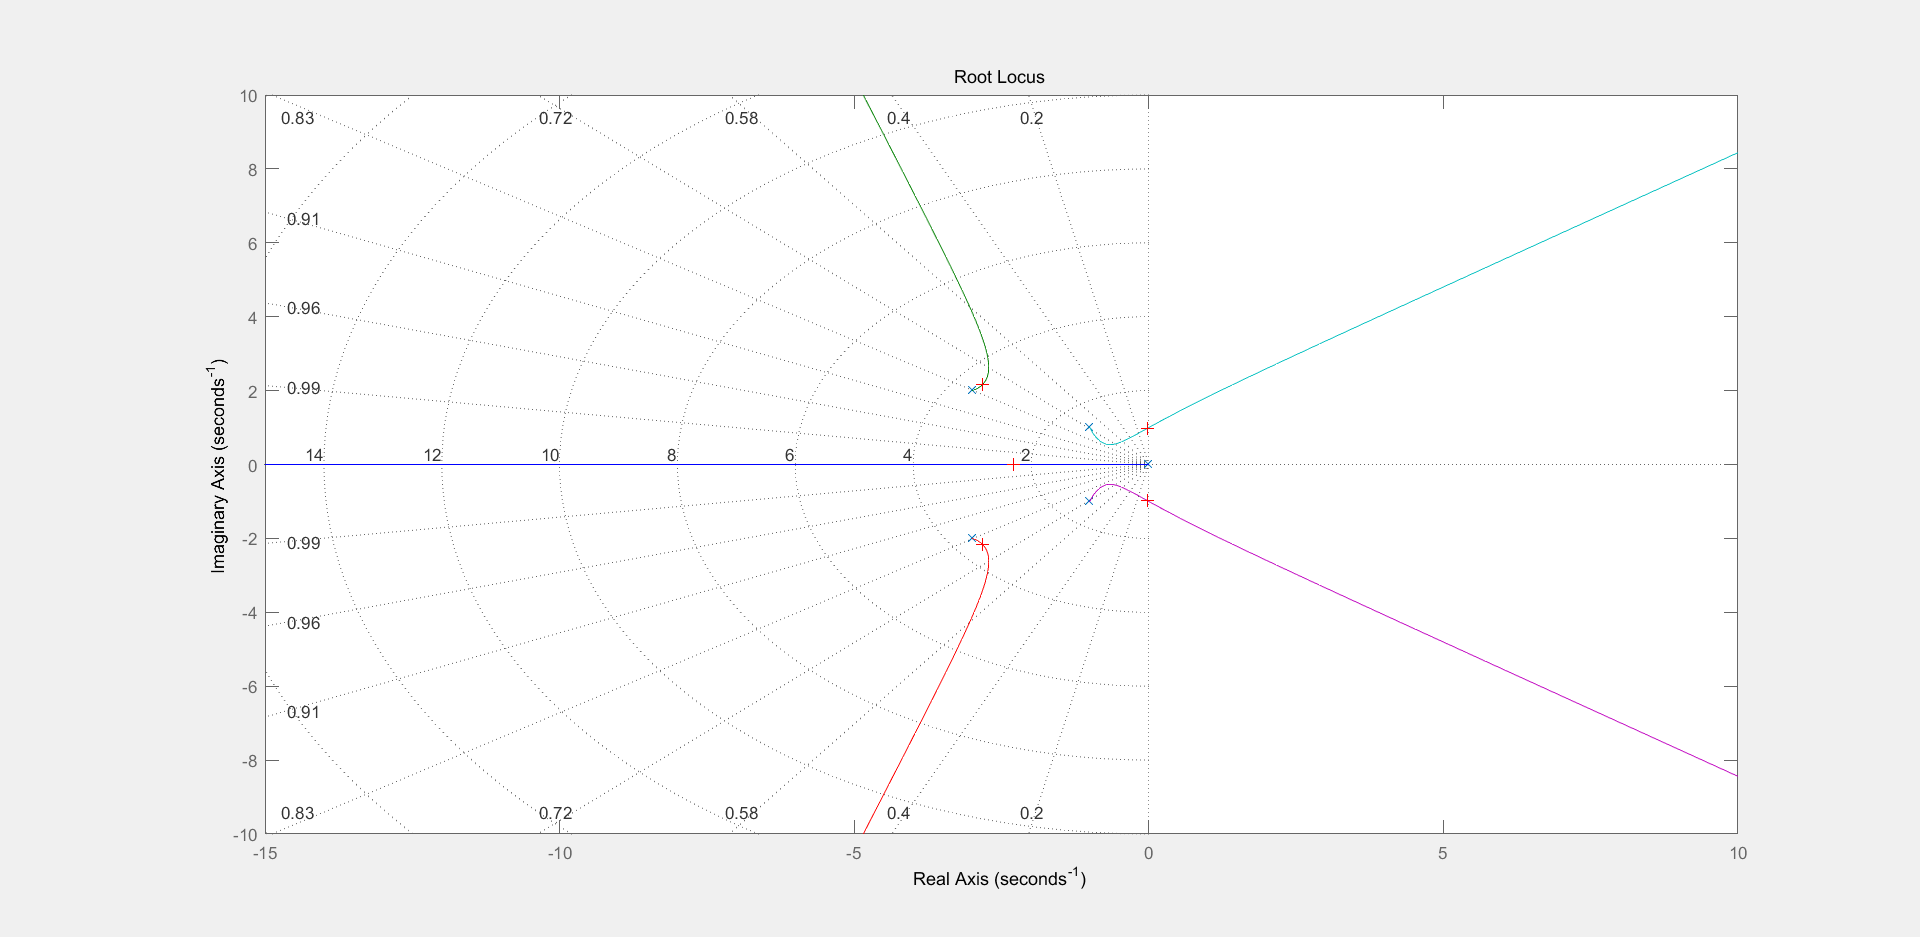

Select a point in the graphics window


selected_point =   -0.0221 + 0.9743i


k = 27.8447

r =   -2.8237 + 2.1606i
  -2.8237 - 2.1606i
  -2.3021 + 0.0000i
  -0.0252 + 0.9778i
  -0.0252 - 0.9778i


%实验2

num=[1]; %定义分子多项式
den=conv([1,0],conv([1,2,2],[1,6,13])); %定义分母多项式
sys=tf(num,den);
rlocus (sys); %绘制系统的根轨迹
grid %画网格标度线
xlabel('Real Axis');
ylabel('Imaginary Axis') ; %给坐标轴加上说明
title('Root Locus'); %给图形加上标题名
[k,r]=rlocfind(sys) %确定临界稳定时的增益值 k 和对应的极点 r 

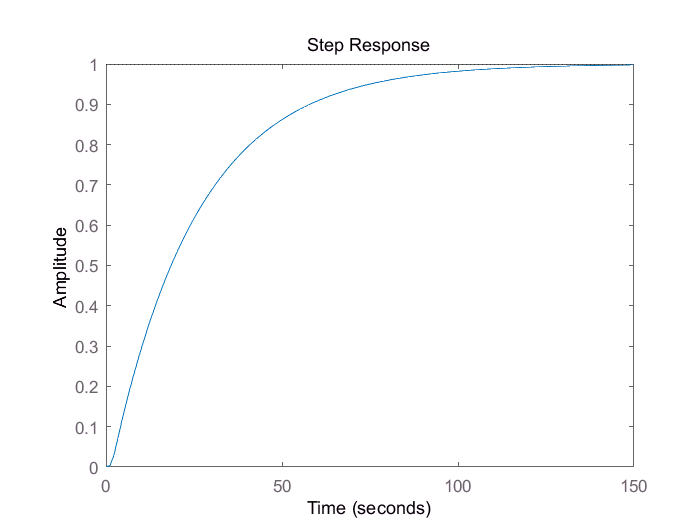

sys_c=feedback(sys,1); %形成单位负反馈闭环系统
figure(2)
step(sys_c) %绘制闭环系统的阶跃响应曲线

%实验3.1
num=[10]; %定义分子多项式
den=conv([1,0,0],conv([5,-1],[1,5])); %定义分母多项式

[z,p,k]=tf2zp(num,den); % tf2zp 将传递函数转换为零极点形式的一个转换函数，可求出零点、极点和增益
p

p =          0
         0
   -5.0000
    0.2000


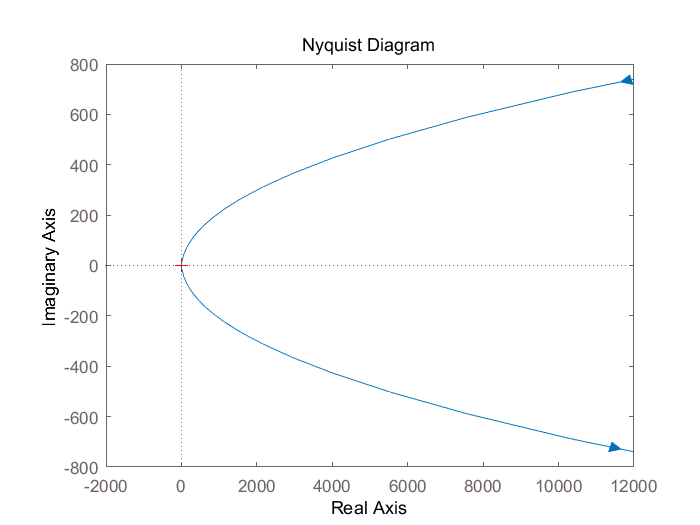

nyquist(num,den)

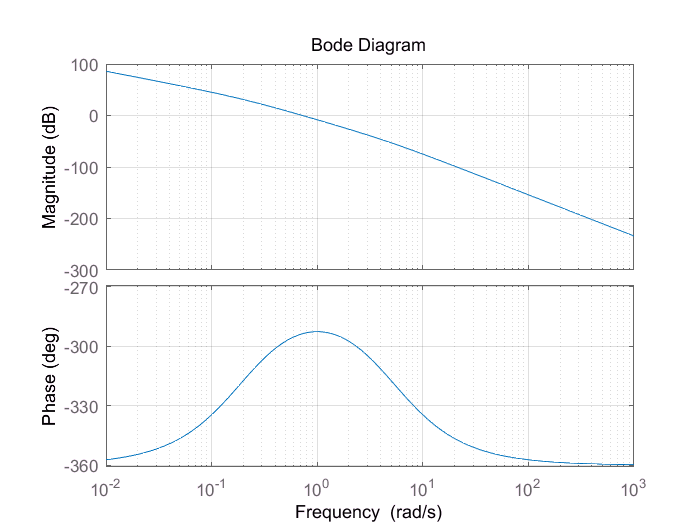

w=logspace(-2,3,100); %即在 10-2 和 103 之间，产生 100 个等距离的点 p。
bode(num,den,w)
grid;

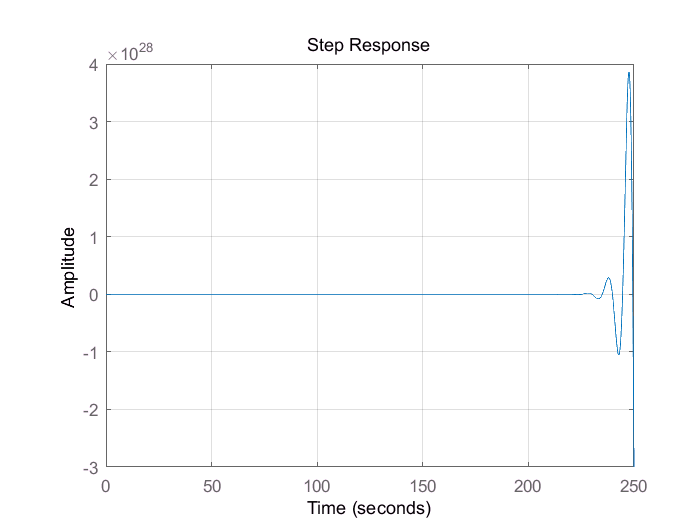

step(num,den+10);
grid;

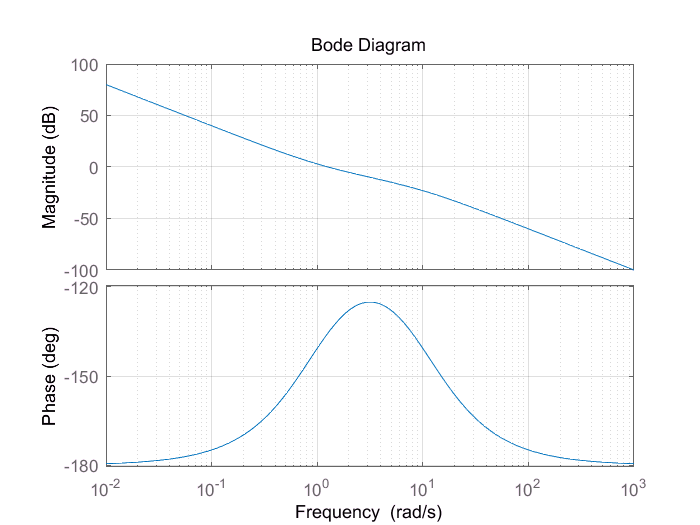

num=[1 1];
den=[0.1 1 0 0];
w=logspace(-2,3,100); %即在 10-2 和 103 之间，产生 100 个等距离的点 p。
bode(num,den,w)
grid;

sys=tf(num,den);
[gm,pm,wcg,wcp]=margin(sys);
gm,pm,wcg,wcp

gm = 0

pm = 44.4594

wcg = 0

wcp = 1.2647